clear all
%constants
Vo=15

Vo = 15

Vref=2.5

Vref = 2.5000


Rb=10e3

Rb = 10000

R1=((Vo*Rb)/Vref)-Rb

R1 = 50000


D=0.5805

D = 0.5805

n=1.2

n = 1.2000


R = 7.5

R = 7.5000

C = 100e-6

C = 1.0000e-04

L = 2.6195e-5

L = 2.6195e-05


Vkmin=2.5

Vkmin = 2.5000

Ik=2e-3

Ik = 0.0020


Vf=1.3

Vf = 1.3000

CTR=1

CTR = 1

%Define transfer function

Dp=1-D

Dp = 0.4195

Dpn=Dp/n

Dpn = 0.3496


s=tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties



f2=Dpn*(1-(s*D*L)/(Dpn^2*R))


f2 =
 
  -5.316e-06 s + 0.3204
  ---------------------
         0.9166
 
Continuous-time transfer function.
Model Properties


r2=R/D

r2 = 12.9199


p = @(x,y)1/((1/x)+(1/y));

Gvc=f2*(p(p(r2,R),1/(s*C)))


Gvc =
 
  -5.316e-06 s + 0.3204
  ---------------------
  9.166e-05 s + 0.1932
 
Continuous-time transfer function.
Model Properties




zpk(Gvc)


ans =
 
  -0.057997 (s-6.028e04)
  ----------------------
         (s+2107)
 
Continuous-time zero/pole/gain model.
Model Properties


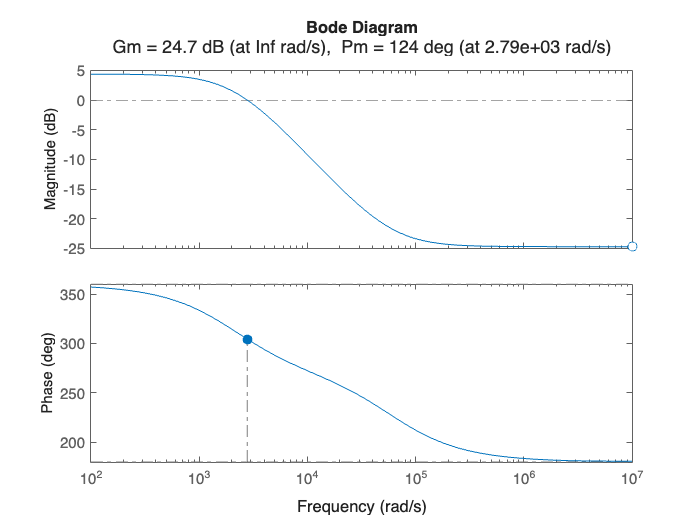



margin(Gvc)

[GM,PM]=margin(Gvc)

GM = 17.2421

PM = 124.3713

% Select crossover frequency

fc = pi*2*5e3

fc = 3.1416e+04


kp=10^(-evalfr(Gvc,fc)/20)

kp = 0.9943

%Compontents for feedback

R5=(Vo-Vf-Vkmin)/Ik

R5 = 5.6000e+03


R4=kp*R5/CTR

R4 = 5.5679e+03





C1=1/((fc/5)*R1)

C1 = 3.1831e-09

C3=1/(fc*5*R4)

C3 = 1.1434e-09



G=(R4*CTR/R5)*(1+s*R1*C1)/(s*R1*C1*(1+s*R4*C3))


G =
 
     0.0001582 s + 0.9943
  ---------------------------
  1.013e-09 s^2 + 0.0001592 s
 
Continuous-time transfer function.
Model Properties


zpk(G)


ans =
 
  1.5618e05 (s+6283)
  ------------------
    s (s+1.571e05)
 
Continuous-time zero/pole/gain model.
Model Properties


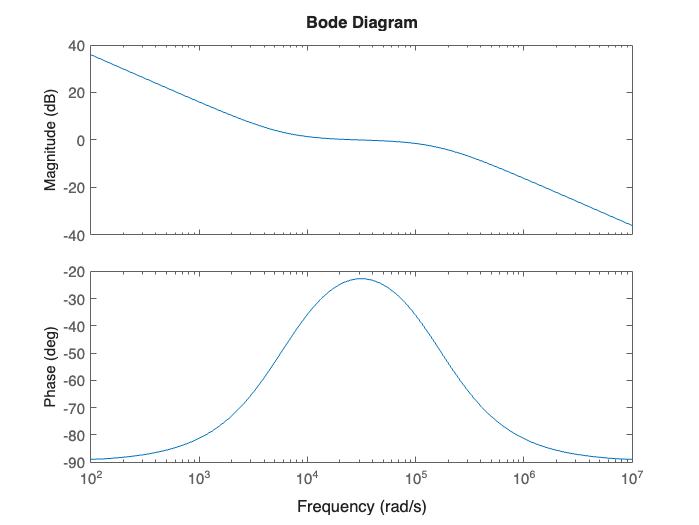



bodeplot(G)

%Loop gain
zpk(Gvc*G)


ans =
 
  -9058 (s-6.028e04) (s+6283)
  ---------------------------
    s (s+1.571e05) (s+2107)
 
Continuous-time zero/pole/gain model.
Model Properties


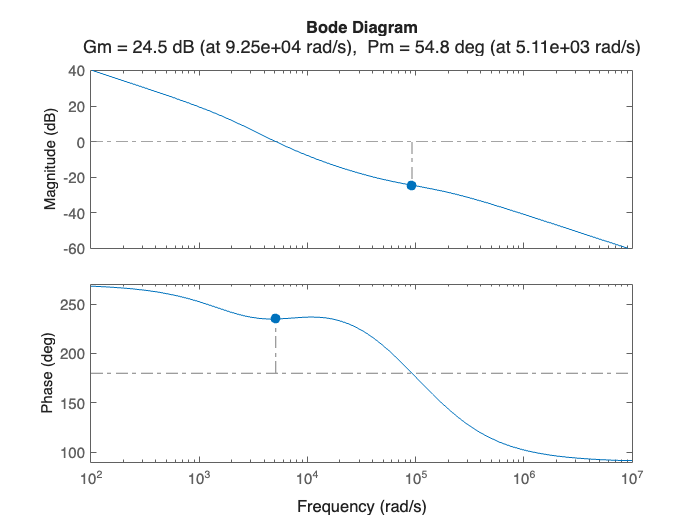

margin(Gvc*G)